Project 1

Setup

clear
close all
clc
format longg

%Set MICE and SPICE data paths
miceDir='mice\';
spiceDataDir='spice\';

if(length(strfind( miceDir , '<<ENTER_PATH>>' )))
    error('enter miceDir path')
end
if(length(strfind( spiceDataDir , '<<ENTER_PATH>>' )))
    error('enter spiceDataDir path')
end

addpath([miceDir 'lib'])
addpath([miceDir 'src\mice\'])

%bsp files for pos and vel of bodies
cspice_furnsh([spiceDataDir 'de440.bsp'])

%orientation info for bodies
cspice_furnsh([spiceDataDir 'pck00011.tpc'])

%leap second information
cspice_furnsh([spiceDataDir 'naif0012.tls'])

ET_E = 0.11564208e+10;
earth = '399';
jupiter = '5';
saturn = '6';
sun = 'SUN';
RF_J2000 = 'J2000';
RF_EJ2000 = 'ECLIPJ2000';
abcorr = 'NONE';
myu_sun = 1.327124400409440e+11;
myu_jup = 1.266865349218000e+08;
R_jup = 7.1492e+04;

Part 1: Validating MICE code

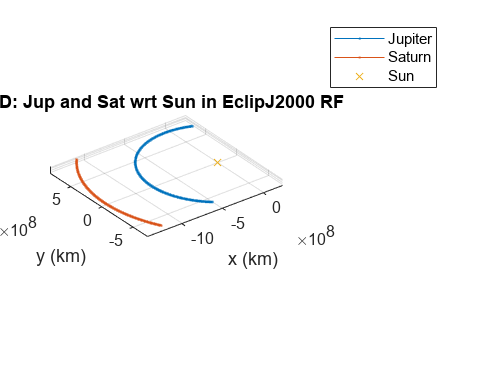


for i = 1:2000 %days
    ET = ET_E + i*60*60*24;

    rvecJup_Sun = mice_spkezr(jupiter, ET, RF_EJ2000, abcorr, sun);
    rJup_Sun(i,1:3) = rvecJup_Sun.state(1:3);
    rvecSat_Sun = mice_spkezr(saturn, ET, RF_EJ2000, abcorr, sun);
    rSat_Sun(i,1:3) = rvecSat_Sun.state(1:3);

    rvecSun_Jup = mice_spkezr(sun, ET, RF_J2000, abcorr, jupiter);
    rSun_Jup(i,1:3) = rvecSun_Jup.state(1:3);
    rvecSat_Jup = mice_spkezr(saturn, ET, RF_J2000, abcorr, jupiter);
    rSat_Jup(i,1:3) = rvecSat_Jup.state(1:3);
end

JupSat_Sun3D = figure;
plot3(rJup_Sun(:,1),rJup_Sun(:,2),rJup_Sun(:,3),'Marker','.','MarkerSize',3)
hold on
plot3(rSat_Sun(:,1),rSat_Sun(:,2),rSat_Sun(:,3),'Marker','.','MarkerSize',3)
plot3(0,0,0,'x')
axis equal
xlabel('x (km)')
ylabel('y (km)')
zlabel('z (km)')
title('3D: Jup and Sat wrt Sun in EclipJ2000 RF')
grid on
legend('Jupiter', 'Saturn', 'Sun')

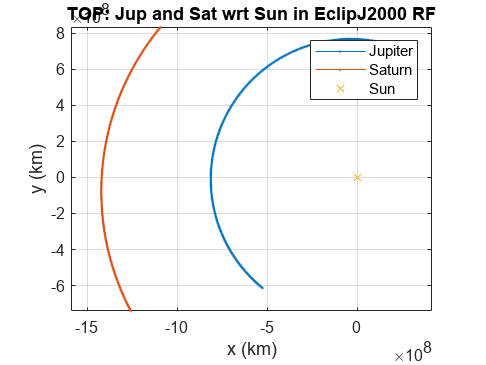


JupSat_Sun2D = figure;
plot(rJup_Sun(:,1),rJup_Sun(:,2),'Marker','.','MarkerSize',3)
hold on
plot(rSat_Sun(:,1),rSat_Sun(:,2),'Marker','.','MarkerSize',3)
plot(0,0,'x')
axis equal
xlabel('x (km)')
ylabel('y (km)')
title('TOP: Jup and Sat wrt Sun in EclipJ2000 RF')
grid on
legend('Jupiter', 'Saturn', 'Sun')

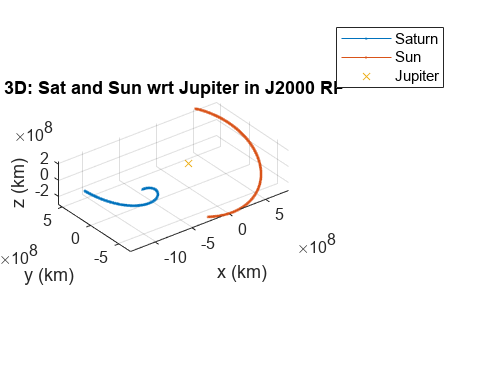


SatSun_Jup3D = figure;
plot3(rSat_Jup(:,1),rSat_Jup(:,2),rSat_Jup(:,3),'Marker','.','MarkerSize',3)
hold on
plot3(rSun_Jup(:,1),rSun_Jup(:,2),rSun_Jup(:,3),'Marker','.','MarkerSize',3)
plot3(0,0,0,'x')
axis equal
xlabel('x (km)')
ylabel('y (km)')
zlabel('z (km)')
title('3D: Sat and Sun wrt Jupiter in J2000 RF')
grid on
legend('Saturn', 'Sun', 'Jupiter')

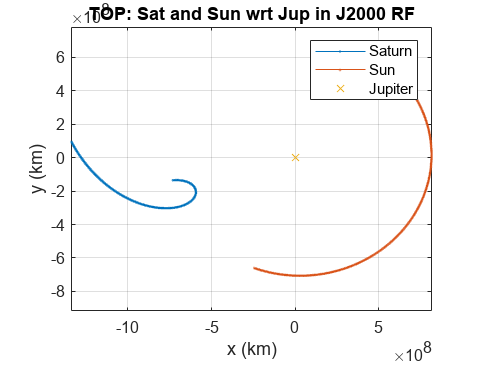


SatSun_Jup2D = figure;
plot(rSat_Jup(:,1),rSat_Jup(:,2),'Marker','.','MarkerSize',3)
hold on
plot(rSun_Jup(:,1),rSun_Jup(:,2),'Marker','.','MarkerSize',3)
plot(0,0,'x')
axis equal
xlabel('x (km)')
ylabel('y (km)')
title('TOP: Sat and Sun wrt Jup in J2000 RF')
grid on
legend('Saturn', 'Sun', 'Jupiter')

Part 2: Validating Lambert solver

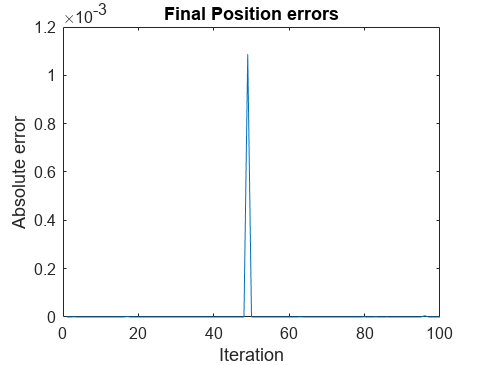

simulations = 100;
rerr_p2 = zeros(simulations, 1);
verr_p2 = zeros(simulations, 1);
for i = 1:simulations
    range = randi(100);
    tof = randi(100);
    r1 = 2*range*rand(3,1) - range;
    r2 = 2*range*rand(3,1) - range;
    lam_rand = lambert(r1, r2, 1, tof, true);
    kep_rand = kepler([r1; lam_rand.v1Vec], tof, 1);
    rerr_p2(i) = abs(norm(r2) - norm(kep_rand.r2Vec));
    verr_p2(i) = abs(norm(lam_rand.v2Vec) - norm(kep_rand.v2Vec));
end
rerr_fig = figure;
plot(rerr_p2)
xlabel('Iteration')
ylabel('Absolute error')
title('Final Position errors')

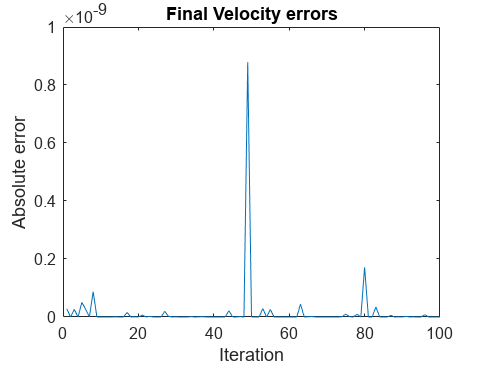


verr_fig = figure;
plot(verr_p2)
xlabel('Iteration')
ylabel('Absolute error')
title('Final Velocity errors')

Part 3: Reproducing given Earth-Jupiter-Saturn example

ET_J_p3 = cspice_str2et('Jan 05, 2039 20:44')

ET_J_p3 =           1231145109.18405


ET_S_p3 = cspice_str2et('Sept 28, 2041 21:08')

ET_S_p3 =           1317287349.18235



E = mice_spkezr(earth, ET_E, RF_EJ2000, abcorr, sun);
rE(1:3) = E.state(1:3);
vE(1:3) = E.state(4:6);
p3_J = mice_spkezr(jupiter, ET_J_p3, RF_EJ2000, abcorr, sun);
rJ_p3(1:3) = p3_J.state(1:3);
vJ_p3(1:3) = p3_J.state(4:6);
p3_S = mice_spkezr(saturn, ET_S_p3, RF_EJ2000, abcorr, sun);
rS_p3(1:3) = p3_S.state(1:3);
vS_p3(1:3) = p3_S.state(4:6);

E2J_p3 = lambert(rE', rJ_p3',myu_sun,(ET_J_p3-ET_E),true);
J2S_p3 = lambert(rJ_p3', rS_p3',myu_sun,(ET_S_p3-ET_J_p3),true);

X1 = [rE'; E2J_p3.v1Vec];
KepE2J_p3.rVec(:,1) = rE';
KepE2J_p3.vVec(:,1) = E2J_p3.v1Vec;
for i = 2:1001
    temp = kepler(X1, (ET_J_p3-ET_E)/1000, myu_sun);
    KepE2J_p3.rVec(:,i) = temp.r2Vec;
    KepE2J_p3.vVec(:,i) = temp.v2Vec;
    X1 = [temp.r2Vec; temp.v2Vec];
end
X1 = [rJ_p3'; J2S_p3.v1Vec];
KepJ2S_p3.rVec(:,1) = rJ_p3';
KepJ2S_p3.vVec(:,1) = J2S_p3.v1Vec;
for i = 2:1001
    temp = kepler(X1, (ET_S_p3-ET_J_p3)/1000, myu_sun);
    KepJ2S_p3.rVec(:,i) = temp.r2Vec;
    KepJ2S_p3.vVec(:,i) = temp.v2Vec;
    X1 = [temp.r2Vec; temp.v2Vec];
end

vinf_plusE_p3 = E2J_p3.v1Vec - vE';
vinf_plusE_norm_p3 = norm(vinf_plusE_p3);
vinf_minusJ_p3 = KepE2J_p3.vVec(:,end) - vJ_p3';
vinf_minusJ_norm_p3 = norm(vinf_minusJ_p3);
vinf_plusJ_p3 = KepJ2S_p3.vVec(:,1) - vJ_p3';
vinf_plusJ_norm_p3 = norm(vinf_plusJ_p3);
verr_p3 = vinf_minusJ_norm_p3 - vinf_plusJ_norm_p3; 
vinf_minusS_p3 = KepJ2S_p3.vVec(:,end) - vS_p3';
vinf_minusS_norm_p3 = norm(vinf_minusS_p3);

delta_p3 = acos(dot(vinf_plusJ_p3,vinf_minusJ_p3)/(vinf_plusJ_norm_p3*vinf_minusJ_norm_p3))

delta_p3 =           2.18508513087382


flybyAlt_p3 = myu_jup*(1/sin(delta_p3/2) - 1)/(vinf_plusJ_norm_p3*vinf_minusJ_norm_p3) - R_jup

flybyAlt_p3 =           391177.910076721



final_pos_p3 = KepJ2S_p3.rVec(:,end)

final_pos_p3 =          -1306119904.60811
         -639446477.360583
          63088993.7114965


final_vel_p3 = KepJ2S_p3.vVec(:,end)

final_vel_p3 =          -3.75319148577208
         -12.5441384798416
         0.430517334130783



vinf_minusS_p3

vinf_minusS_p3 =          -7.48919935288359
         -3.84027486889454
         0.428378600046949


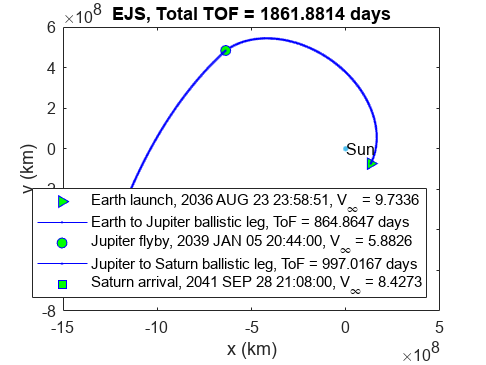


p3 = figure;
plot(KepE2J_p3.rVec(1,1),KepE2J_p3.rVec(2,1),'>','MarkerEdgeColor','blue','MarkerFaceColor','green');
hold on
plot(KepE2J_p3.rVec(1,:),KepE2J_p3.rVec(2,:),'Color','blue','Marker','.','MarkerSize',3,'MarkerEdgeColor','blue');
plot(KepE2J_p3.rVec(1,end),KepE2J_p3.rVec(2,end),'o','MarkerEdgeColor','blue','MarkerFaceColor','green');
plot(KepJ2S_p3.rVec(1,:),KepJ2S_p3.rVec(2,:),'Color','blue','Marker','.','MarkerSize',3,'MarkerEdgeColor','blue');
plot(KepJ2S_p3.rVec(1,end),KepJ2S_p3.rVec(2,end),'s','MarkerEdgeColor','blue','MarkerFaceColor','green');
plot(0,0,'.','MarkerSize',10)
text(0,0,'Sun')
legend(['Earth launch, ' cspice_et2utc(ET_E,'C',0) ', V_{\infty} = ' num2str(vinf_plusE_norm_p3)], ...
    ['Earth to Jupiter ballistic leg, ToF = ' num2str((ET_J_p3-ET_E)/(60*60*24)) ' days'], ...
    ['Jupiter flyby, ' cspice_et2utc(ET_J_p3,'C',0) ', V_{\infty} = ' num2str((vinf_plusJ_norm_p3+vinf_minusJ_norm_p3)/2)], ...
    ['Jupiter to Saturn ballistic leg, ToF = ' num2str((ET_S_p3-ET_J_p3)/(60*60*24)) ' days'], ...
    ['Saturn arrival, ' cspice_et2utc(ET_S_p3,'C',0) ', V_{\infty} = ' num2str(vinf_minusS_norm_p3)], ...
    'Location','southeast');
xlabel('x (km)')
ylabel('y (km)')
title(['EJS, Total TOF = ' num2str((ET_S_p3-ET_E)/(60*60*24)) ' days'])

Part 4: Computing family of solutions for feasible Jupiter flyby dates

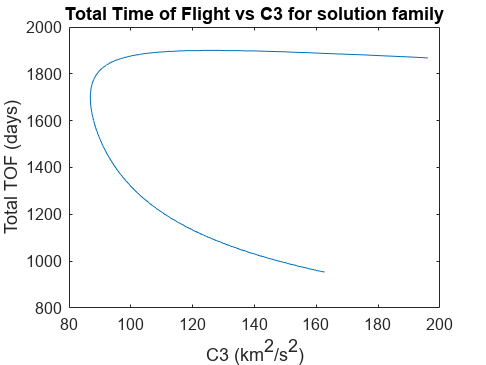

verrMax = 50e-3; %km/s
ET_J = [];
ET_J_temp_temp = [];
ET_S = [];
ET_S_temp_temp = [];
verr = [];
verr_temp_temp = [];
vinf_plusE_norm = [];
vinf_minusS_norm = [];
C3 = [];
iter = 0;
lam_call = 0;
for i = 1:2000
    %Set iteration time for arrival at Jupiter
    ET_J_temp = ET_E + i*60*60*24;
    %Get position and velocity of Jupiter at set iteration time
    J_temp = mice_spkezr(jupiter, ET_J_temp, RF_EJ2000, abcorr, sun);
    rJ_temp(1:3,1) = J_temp.state(1:3);
    vJ_temp(1:3,1) = J_temp.state(4:6);
    %Compute velocities of spacecraft for the first ballistic leg
    E2J_temp = lambert(rE',rJ_temp,myu_sun,(ET_J_temp-ET_E),true);
    %Check that the launch C3 is smaller than 200 km^2/s^2
    vinf_plusE_temp = E2J_temp.v1Vec - vE';
    vinf_plusE_norm_temp = norm(vinf_plusE_temp);
    C3_launch = vinf_plusE_norm_temp^2;
    if C3_launch > 200
        continue
    end
    %Compute arrival V infinity at Jupiter
    vinf_minusJ_temp = E2J_temp.v2Vec - vJ_temp;
    vinf_minusJ_norm_temp = norm(vinf_minusJ_temp);
    %Iterate possible candidates for second ballistic leg
    for j = i+1:2000
        %Set iteration time for arrival at Saturn
        ET_S_temp = ET_E + j*60*60*24;
        %Get position and velocity of Saturn at set iteration time
        S_temp = mice_spkezr(saturn, ET_S_temp, RF_EJ2000, abcorr, sun);
        rS_temp(1:3,1) = S_temp.state(1:3);
        vS_temp(1:3,1) = S_temp.state(4:6);
        %Compute velocities of spacecraft for the second ballistic leg
        J2S_temp = lambert(rJ_temp,rS_temp,myu_sun,(ET_S_temp-ET_J_temp),true);
        %Increment number of calls
        lam_call = lam_call + 1;
        %Compute departure V infinity at Jupiter
        vinf_plusJ_temp = J2S_temp.v1Vec - vJ_temp;
        vinf_plusJ_norm_temp = norm(vinf_plusJ_temp);
        %Check that arrival and departure V infinities for
        %flyby at Jupiter are within set velocity error of
        %one another, and that the turn angle is smaller
        %than the maximum turn angle
        verr_temp = abs(vinf_plusJ_norm_temp - vinf_minusJ_norm_temp);
        delta_temp = acos(dot(vinf_plusJ_temp,vinf_minusJ_temp)/(vinf_plusJ_norm_temp*vinf_minusJ_norm_temp));
        delta_max_temp = 2*asin(myu_jup/(myu_jup + R_jup*vinf_plusJ_norm_temp*vinf_minusJ_norm_temp));
        if (verr_temp < verrMax) && (delta_temp <= delta_max_temp)
            ET_J_temp_temp(end+1) = ET_J_temp;
            ET_S_temp_temp(end+1) = ET_S_temp;
            verr_temp_temp(end+1) = verr_temp;
            vinf_minusS_norm_temp = norm(J2S_temp.v2Vec - vS_temp);
        end
    end
    if size(verr_temp_temp)
        i_verr_min = find(min(verr_temp_temp));
        verr(end+1) = min(verr_temp_temp);
        verr_temp_temp = [];
        ET_J(end+1) = ET_J_temp_temp(i_verr_min);
        ET_J_temp_temp = [];
        ET_S(end+1) = ET_S_temp_temp(i_verr_min);
        ET_S_temp_temp = [];
        C3(end+1) = C3_launch;
        vinf_minusS_norm(end+1) = vinf_minusS_norm_temp(i_verr_min);
        vinf_minusS_norm_temp = [];
        vinf_plusE_norm(end+1) = vinf_plusE_norm_temp;
        iter = iter + 1;
    end
end

TOF_vs_C3 = figure;
plot(C3, (ET_S-ET_E)/(60*60*24))
xlabel('C3 (km^{2}/s^{2})')
ylabel('Total TOF (days)')
title('Total Time of Flight vs C3 for solution family')

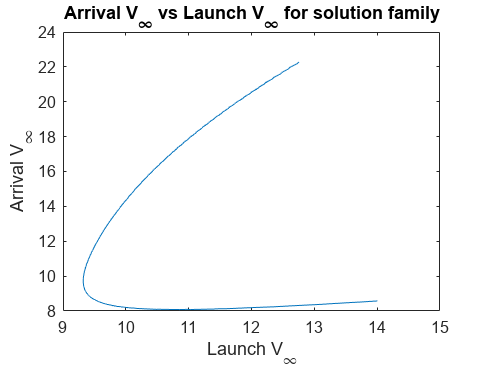


Arrival_vs_Launch_vinf = figure;
plot(vinf_plusE_norm, vinf_minusS_norm)
xlabel('Launch V_{\infty}')
ylabel('Arrival V_{\infty}')
title('Arrival V_{\infty} vs Launch V_{\infty} for solution family')

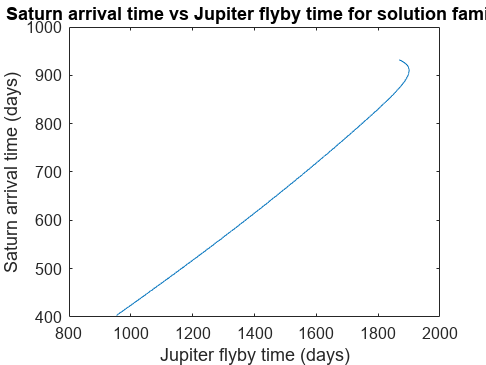


Sat_vs_Jup_time = figure;
plot((ET_S-ET_E)/(60*60*24), (ET_J-ET_E)/(60*60*24))
xlabel('Jupiter flyby time (days)')
ylabel('Saturn arrival time (days)')
title('Saturn arrival time vs Jupiter flyby time for solution family')

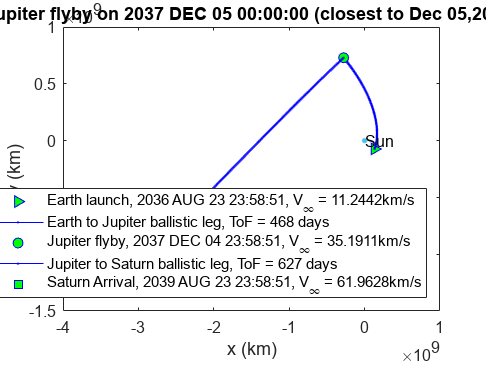


%Plot for Dec 05, 2037
ET_J_tmp = abs(ET_J - cspice_str2et('Dec 05, 2037'));
[ET_J_p4, i_ET_J_p4] = min(ET_J_tmp);

J_Dec05 = mice_spkezr(jupiter, ET_J(i_ET_J_p4), RF_EJ2000, abcorr, sun);
rJ_Dec05(1:3) = J_Dec05.state(1:3);
vJ_Dec05(1:3) = J_Dec05.state(4:6);
S_Dec05 = mice_spkezr(saturn, ET_S(i_ET_J_p4), RF_EJ2000, abcorr, sun);
rS_Dec05(1:3) = S_Dec05.state(1:3);
vS_Dec05(1:3) = S_Dec05.state(4:6);

E2J_Dec05 = lambert(rE', rJ_Dec05',myu_sun,(ET_J(i_ET_J_p4)-ET_E),true);
J2S_Dec05 = lambert(rJ_Dec05', rS_Dec05',myu_sun,(ET_S(i_ET_J_p4)-ET_J_p3),true);

X1 = [rE'; E2J_Dec05.v1Vec];
KepE2J_Dec05.rVec(:,1) = rE';
KepE2J_Dec05.vVec(:,1) = E2J_Dec05.v1Vec;
for i = 2:1001
    temp = kepler(X1, (ET_J(i_ET_J_p4)-ET_E)/1000, myu_sun);
    KepE2J_Dec05.rVec(:,i) = temp.r2Vec;
    KepE2J_Dec05.vVec(:,i) = temp.v2Vec;
    X1 = [temp.r2Vec; temp.v2Vec];
end
X1 = [rJ_Dec05'; J2S_Dec05.v1Vec];
KepJ2S_Dec05.rVec(:,1) = rJ_Dec05';
KepJ2S_Dec05.vVec(:,1) = J2S_Dec05.v1Vec;
for i = 2:1001
    temp = kepler(X1, (ET_S(i_ET_J_p4)-ET_J(i_ET_J_p4))/1000, myu_sun);
    KepJ2S_Dec05.rVec(:,i) = temp.r2Vec;
    KepJ2S_Dec05.vVec(:,i) = temp.v2Vec;
    X1 = [temp.r2Vec; temp.v2Vec];
end

vinf_plusE_Dec05 = E2J_Dec05.v1Vec - vE';
vinf_plusE_norm_Dec05 = norm(vinf_plusE_Dec05);
vinf_minusJ_Dec05 = KepE2J_Dec05.vVec(:,end) - vJ_Dec05';
vinf_minusJ_norm_Dec05 = norm(vinf_minusJ_Dec05);
vinf_plusJ_Dec05 = KepJ2S_Dec05.vVec(:,1) - vJ_Dec05';
vinf_plusJ_norm_Dec05 = norm(vinf_plusJ_Dec05);
verr_Dec05 = vinf_minusJ_norm_Dec05 - vinf_plusJ_norm_Dec05; 
vinf_minusS_Dec05 = KepJ2S_Dec05.vVec(:,end) - vS_Dec05';
vinf_minusS_norm_Dec05 = norm(vinf_minusS_Dec05);

Dec05 = figure;
plot(KepE2J_Dec05.rVec(1,1),KepE2J_Dec05.rVec(2,1),'>','MarkerEdgeColor','blue','MarkerFaceColor','green');
hold on
plot(KepE2J_Dec05.rVec(1,:),KepE2J_Dec05.rVec(2,:),'Color','blue','Marker','.','MarkerSize',3,'MarkerEdgeColor','blue');
plot(KepE2J_Dec05.rVec(1,end),KepE2J_Dec05.rVec(2,end),'o','MarkerEdgeColor','blue','MarkerFaceColor','green');
plot(KepJ2S_Dec05.rVec(1,:),KepJ2S_Dec05.rVec(2,:),'Color','blue','Marker','.','MarkerSize',3,'MarkerEdgeColor','blue');
plot(KepJ2S_Dec05.rVec(1,end),KepJ2S_Dec05.rVec(2,end),'s','MarkerEdgeColor','blue','MarkerFaceColor','green');
plot(0,0,'.','MarkerSize',10)
text(0,0,'Sun')
legend(['Earth launch, ' cspice_et2utc(ET_E,'C',0) ', V_{\infty} = ' num2str(vinf_plusE_norm_Dec05) 'km/s'], ...
    ['Earth to Jupiter ballistic leg, ToF = ' num2str((ET_J(i_ET_J_p4)-ET_E)/(60*60*24)) ' days'], ...
    ['Jupiter flyby, ' cspice_et2utc(ET_J(i_ET_J_p4),'C',0) ', V_{\infty} = ' num2str((vinf_plusJ_norm_Dec05+vinf_minusJ_norm_Dec05)/2) 'km/s'], ...
    ['Jupiter to Saturn ballistic leg, ToF = ' num2str((ET_S(i_ET_J_p4)-ET_J(i_ET_J_p4))/(60*60*24)) ' days'], ...
    ['Saturn Arrival, ' cspice_et2utc(ET_S(i_ET_J_p4),'C',0) ', V_{\infty} = ' num2str(vinf_minusS_norm_Dec05) 'km/s'], ...
    'Location','southeast');
xlabel('x (km)')
ylabel('y (km)')
title(['Jupiter flyby on ' cspice_et2utc(ET_J(i_ET_J_p4),'C',0) ' (closest to Dec 05,2037)'])

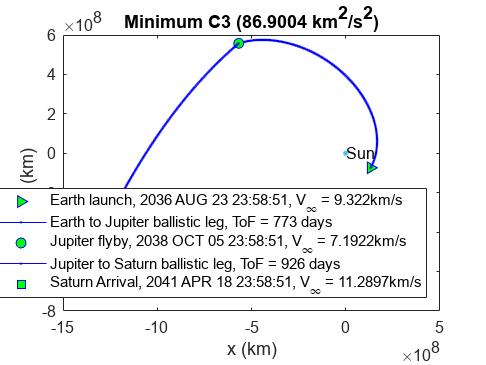


%Plot for C3 min
[C3_min, i_C3_min] = min(C3);

J_C3_min = mice_spkezr(jupiter, ET_J(i_C3_min), RF_EJ2000, abcorr, sun);
rJ_C3_min(1:3) = J_C3_min.state(1:3);
vJ_C3_min(1:3) = J_C3_min.state(4:6);
S_C3_min = mice_spkezr(saturn, ET_S(i_C3_min), RF_EJ2000, abcorr, sun);
rS_C3_min(1:3) = S_C3_min.state(1:3);
vS_C3_min(1:3) = S_C3_min.state(4:6);

E2J_C3_min = lambert(rE', rJ_C3_min',myu_sun,(ET_J(i_C3_min)-ET_E),true);
J2S_C3_min = lambert(rJ_C3_min', rS_C3_min',myu_sun,(ET_S(i_C3_min)-ET_J_p3),true);

X1 = [rE'; E2J_C3_min.v1Vec];
KepE2J_C3_min.rVec(:,1) = rE';
KepE2J_C3_min.vVec(:,1) = E2J_C3_min.v1Vec;
for i = 2:1001
    temp = kepler(X1, (ET_J(i_C3_min)-ET_E)/1000, myu_sun);
    KepE2J_C3_min.rVec(:,i) = temp.r2Vec;
    KepE2J_C3_min.vVec(:,i) = temp.v2Vec;
    X1 = [temp.r2Vec; temp.v2Vec];
end
X1 = [rJ_C3_min'; J2S_C3_min.v1Vec];
KepJ2S_C3_min.rVec(:,1) = rJ_C3_min';
KepJ2S_C3_min.vVec(:,1) = J2S_C3_min.v1Vec;
for i = 2:1001
    temp = kepler(X1, (ET_S(i_C3_min)-ET_J(i_C3_min))/1000, myu_sun);
    KepJ2S_C3_min.rVec(:,i) = temp.r2Vec;
    KepJ2S_C3_min.vVec(:,i) = temp.v2Vec;
    X1 = [temp.r2Vec; temp.v2Vec];
end

vinf_plusE_C3_min = E2J_C3_min.v1Vec - vE';
vinf_plusE_norm_C3_min = norm(vinf_plusE_C3_min);
vinf_minusJ_C3_min = KepE2J_C3_min.vVec(:,end) - vJ_C3_min';
vinf_minusJ_norm_C3_min = norm(vinf_minusJ_C3_min);
vinf_plusJ_C3_min = KepJ2S_C3_min.vVec(:,1) - vJ_C3_min';
vinf_plusJ_norm_C3_min = norm(vinf_plusJ_C3_min);
vinf_minusS_C3_min = KepJ2S_C3_min.vVec(:,end) - vS_C3_min';
vinf_minusS_norm_C3_min = norm(vinf_minusS_C3_min);

C3_min_fig = figure;
plot(KepE2J_C3_min.rVec(1,1),KepE2J_C3_min.rVec(2,1),'>','MarkerEdgeColor','blue','MarkerFaceColor','green');
hold on
plot(KepE2J_C3_min.rVec(1,:),KepE2J_C3_min.rVec(2,:),'Color','blue','Marker','.','MarkerSize',3,'MarkerEdgeColor','blue');
plot(KepE2J_C3_min.rVec(1,end),KepE2J_C3_min.rVec(2,end),'o','MarkerEdgeColor','blue','MarkerFaceColor','green');
plot(KepJ2S_C3_min.rVec(1,:),KepJ2S_C3_min.rVec(2,:),'Color','blue','Marker','.','MarkerSize',3,'MarkerEdgeColor','blue');
plot(KepJ2S_C3_min.rVec(1,end),KepJ2S_C3_min.rVec(2,end),'s','MarkerEdgeColor','blue','MarkerFaceColor','green');
plot(0,0,'.','MarkerSize',10)
text(0,0,'Sun')
legend(['Earth launch, ' cspice_et2utc(ET_E,'C',0) ', V_{\infty} = ' num2str(vinf_plusE_norm_C3_min) 'km/s'], ...
    ['Earth to Jupiter ballistic leg, ToF = ' num2str((ET_J(i_C3_min)-ET_E)/(60*60*24)) ' days'], ...
    ['Jupiter flyby, ' cspice_et2utc(ET_J(i_C3_min),'C',0) ', V_{\infty} = ' num2str((vinf_plusJ_norm_C3_min+vinf_minusJ_norm_C3_min)/2) 'km/s'], ...
    ['Jupiter to Saturn ballistic leg, ToF = ' num2str((ET_S(i_C3_min)-ET_J(i_C3_min))/(60*60*24)) ' days'], ...
    ['Saturn Arrival, ' cspice_et2utc(ET_S(i_C3_min),'C',0) ', V_{\infty} = ' num2str(vinf_minusS_norm_C3_min) 'km/s'], ...
    'Location','southeast');
xlabel('x (km)')
ylabel('y (km)')
title(['Minimum C3 (' num2str(C3_min) ' km^{2}/s^{2})'])

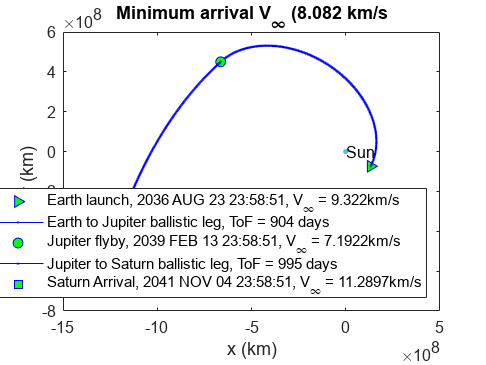


%Plot for minimum arrival Vinf
[V_inf_min, i_vinf_arr_min] = min(vinf_minusS_norm);

J_vinf_arr_min = mice_spkezr(jupiter, ET_J(i_vinf_arr_min), RF_EJ2000, abcorr, sun);
rJ_vinf_arr_min(1:3) = J_vinf_arr_min.state(1:3);
vJ_vinf_arr_min(1:3) = J_vinf_arr_min.state(4:6);
S_vinf_arr_min = mice_spkezr(saturn, ET_S(i_vinf_arr_min), RF_EJ2000, abcorr, sun);
rS_vinf_arr_min(1:3) = S_vinf_arr_min.state(1:3);
vS_vinf_arr_min(1:3) = S_vinf_arr_min.state(4:6);

E2J_vinf_arr_min = lambert(rE', rJ_vinf_arr_min',myu_sun,(ET_J(i_vinf_arr_min)-ET_E),true);
J2S_vinf_arr_min = lambert(rJ_vinf_arr_min', rS_vinf_arr_min',myu_sun,(ET_S(i_vinf_arr_min)-ET_J_p3),true);

X1 = [rE'; E2J_vinf_arr_min.v1Vec];
KepE2J_vinf_arr_min.rVec(:,1) = rE';
KepE2J_vinf_arr_min.vVec(:,1) = E2J_vinf_arr_min.v1Vec;
for i = 2:1001
    temp = kepler(X1, (ET_J(i_vinf_arr_min)-ET_E)/1000, myu_sun);
    KepE2J_vinf_arr_min.rVec(:,i) = temp.r2Vec;
    KepE2J_vinf_arr_min.vVec(:,i) = temp.v2Vec;
    X1 = [temp.r2Vec; temp.v2Vec];
end
X1 = [rJ_vinf_arr_min'; J2S_vinf_arr_min.v1Vec];
KepJ2S_vinf_arr_min.rVec(:,1) = rJ_vinf_arr_min';
KepJ2S_vinf_arr_min.vVec(:,1) = J2S_vinf_arr_min.v1Vec;
for i = 2:1001
    temp = kepler(X1, (ET_S(i_vinf_arr_min)-ET_J(i_vinf_arr_min))/1000, myu_sun);
    KepJ2S_vinf_arr_min.rVec(:,i) = temp.r2Vec;
    KepJ2S_vinf_arr_min.vVec(:,i) = temp.v2Vec;
    X1 = [temp.r2Vec; temp.v2Vec];
end

vinf_plusE_vinf_arr_min = E2J_vinf_arr_min.v1Vec - vE';
vinf_plusE_norm_vinf_arr_min = norm(vinf_plusE_vinf_arr_min);
vinf_minusJ_vinf_arr_min = KepE2J_vinf_arr_min.vVec(:,end) - vJ_vinf_arr_min';
vinf_minusJ_norm_vinf_arr_min = norm(vinf_minusJ_vinf_arr_min);
vinf_plusJ_vinf_arr_min = KepJ2S_vinf_arr_min.vVec(:,1) - vJ_vinf_arr_min';
vinf_plusJ_norm_vinf_arr_min = norm(vinf_plusJ_vinf_arr_min);
vinf_minusS_vinf_arr_min = KepJ2S_vinf_arr_min.vVec(:,end) - vS_vinf_arr_min';
vinf_minusS_norm_vinf_arr_min = norm(vinf_minusS_C3_min);

vinf_arr_min = figure;
plot(KepE2J_vinf_arr_min.rVec(1,1),KepE2J_vinf_arr_min.rVec(2,1),'>','MarkerEdgeColor','blue','MarkerFaceColor','green');
hold on
plot(KepE2J_vinf_arr_min.rVec(1,:),KepE2J_vinf_arr_min.rVec(2,:),'Color','blue','Marker','.','MarkerSize',3,'MarkerEdgeColor','blue');
plot(KepE2J_vinf_arr_min.rVec(1,end),KepE2J_vinf_arr_min.rVec(2,end),'o','MarkerEdgeColor','blue','MarkerFaceColor','green');
plot(KepJ2S_vinf_arr_min.rVec(1,:),KepJ2S_vinf_arr_min.rVec(2,:),'Color','blue','Marker','.','MarkerSize',3,'MarkerEdgeColor','blue');
plot(KepJ2S_vinf_arr_min.rVec(1,end),KepJ2S_vinf_arr_min.rVec(2,end),'s','MarkerEdgeColor','blue','MarkerFaceColor','green');
plot(0,0,'.','MarkerSize',10)
text(0,0,'Sun')
legend(['Earth launch, ' cspice_et2utc(ET_E,'C',0) ', V_{\infty} = ' num2str(vinf_plusE_norm_C3_min) 'km/s'], ...
    ['Earth to Jupiter ballistic leg, ToF = ' num2str((ET_J(i_vinf_arr_min)-ET_E)/(60*60*24)) ' days'], ...
    ['Jupiter flyby, ' cspice_et2utc(ET_J(i_vinf_arr_min),'C',0) ', V_{\infty} = ' num2str((vinf_plusJ_norm_C3_min+vinf_minusJ_norm_C3_min)/2) 'km/s'], ...
    ['Jupiter to Saturn ballistic leg, ToF = ' num2str((ET_S(i_vinf_arr_min)-ET_J(i_vinf_arr_min))/(60*60*24)) ' days'], ...
    ['Saturn Arrival, ' cspice_et2utc(ET_S(i_vinf_arr_min),'C',0) ', V_{\infty} = ' num2str(vinf_minusS_norm_C3_min) 'km/s'], ...
    'Location','southeast');
xlabel('x (km)')
ylabel('y (km)')
title(['Minimum arrival V_{\infty} (' num2str(V_inf_min) ' km/s)'])